# One sample analyses

**Author:** Scott Campit

## Summary

This script analyzes single cell line datasets and plots the relationship between fluxes and histone levels

## Load datasets

### Khao et al., 2020

#### Load metabolic flux data

load ~/Data/CBM/eGEM/_Fluxes/Khao_no_gamma.mat

#### Load proteomics data

filepaths = '~/Data/Proteomics/Dou/Khoa et al 2020 Histone PTMs.xlsx';
sheet = 'Single modifications';
khao_proteomics = readcell(filepaths, 'Sheet', sheet);

Extract information

marker_labels = string(khao_proteomics(2:end, 1));
log2fc = str2double(string(khao_proteomics(2:end, 14)));
log2fc(isnan(log2fc)) = 0;
pvalues = str2double(string(khao_proteomics(2:end, 15))); 
pvalues(isnan(pvalues)) = 0;

Sort the data

[~, idx] = sort(marker_labels);
marker_labels = marker_labels(idx);
log2fc = log2fc(idx);

Reorganize the data

marker_pos = [15, 16, 17, 14, ... % H3K4  me1, me2, me3, ac
              27, 28, 29, 26, ... % H3K9  me1, me2, me3, ac
              8, 9, 10, 7, ...    % H3K27 me1, me2, me3, ac
              11, 12, 13, ...     % H3K36 me1, me2, me3
              23, 24, 25, 22];    % H3K79 me1, me2, me3, ac
          
marker_labels = marker_labels(marker_pos);
log2fc = log2fc(marker_pos);
pvalues = pvalues(marker_pos);

#### Plot the metabolic flux versus the relative proteomics levels

flux_pos = [6, 7, 8, 9, ...
            10, 11, 12, 13, ...
            14, 15, 16, 17, ...
            18, 19, 20, ...
            22, 23, 24, 25];
        
for i = 1:length(flux_pos)
    flux_data{i} = flux{flux_pos(i)};
end

rxn_pos = [3780, 3781, 3782, 3783, ... % H3K4  me1, me2, me3, ac
           3784, 3785, 3786, 3787, ... % H3K9  me1, me2, me3, ac
           3788, 3789, 3790, 3791, ... % H3K27 me1, me2, me3, ac
           3792, 3793, 3794, ...       % H3K36 me1, me2, me3
           3796, 3797, 3798, 3799];    % H3K79 me1, me2, me3, ac
for i = 1:length(rxn_pos)
    rxn_flux(i, 1) = flux_data{i}(rxn_pos(i));
end

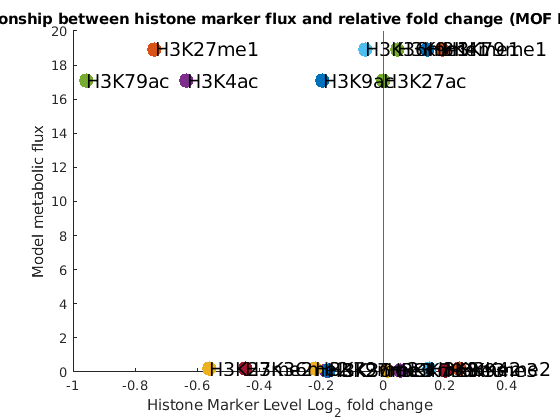

figure;
% Note that all markers were not differentially expressed
%for i = 1:length(rxn_flux)
%    if pvalues(i) > 0.05
%        colors(i) = 'k';
%   else
%        colors(i) = 'r';
%    end
%end
for i = 1:length(rxn_flux)
    hold on;
    scatter(log2fc(i), rxn_flux(i), 120, 'filled');
    hold off;
end
xlabel("Histone Marker Level Log_{2} fold change");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and relative fold change (MOF KO / WT)");
text(log2fc, rxn_flux, marker_labels, 'FontSize', 14)
xline(0)

### Lu et al., 2020

#### Load metabolic flux data

load ~/Data/CBM/eGEM/_Fluxes/lu_no_gamma.mat

#### Load proteomics data

filepaths = '~/Data/Proteomics/Garcia/histone-PTM-EMT.xlsx';
sheet = '(B) Single PTMs';
lu_proteomics = readcell(filepaths, 'Sheet', sheet);

Extract information

marker_labels = string(lu_proteomics(2:end, 1));
colnames = string(lu_proteomics(1, 2:end));
data = str2double(string(lu_proteomics(2:end, 2:end)));
data(isnan(data)) = 0;
data = [mean(data(:, 1:9), 2), mean(data(:, 10:18), 2), mean(data(:, 19:end), 2)];
log2fc = [log2(data(:, 2)) - log2(data(:, 1)), log2(data(:, 3)) - log2(data(:, 1))];

Sort the data

[~, idx] = sort(marker_labels);
marker_labels = marker_labels(idx);
log2fc = log2fc(idx);

Reorganize the data

marker_pos = [23, 24, 25, 22, ... % H3K4  me1, me2, me3, ac
              35, 36, 37, 34, ... % H3K9  me1, me2, me3, ac
              10, 11, 12, 9, ...    % H3K27 me1, me2, me3, ac
              13, 14, 15, ...     % H3K36 me1, me2, me3
              31, 32, 33, 30];    % H3K79 me1, me2, me3, ac
          
marker_labels = marker_labels(marker_pos);
data   = data(marker_pos, :);
log2fc = log2fc(marker_pos, :);

#### Plot the metabolic flux versus the relative proteomics levels

flux_pos = [6, 7, 8, 9, ...     % H3K4  me1, me2, me3, ac
            10, 11, 12, 13, ... % H3K9  me1, me2, me3, ac
            14, 15, 16, 17, ... % H3K27 me1, me2, me3, ac
            18, 19, 20, ...     % H3K36 me1, me2, me3
            22, 23, 24, 25];    % H3K79 me1, me2, me3, ac
        
for i = 1:length(flux_pos)
    for j = 1:size(all_data, 1)
        fx = all_data{j, 2};
        flux_data{i, j} = fx{flux_pos(i)};
    end
end

rxn_pos = [3780, 3781, 3782, 3783, ... % H3K4  me1, me2, me3, ac
           3784, 3785, 3786, 3787, ... % H3K9  me1, me2, me3, ac
           3788, 3789, 3790, 3791, ... % H3K27 me1, me2, me3, ac
           3792, 3793, 3794, ...       % H3K36 me1, me2, me3
           3796, 3797, 3798, 3799];    % H3K79 me1, me2, me3, ac
       
for i = 1:length(rxn_pos)
    for j = 1:size(flux_data, 2)
        rxn_flux(i, j) = flux_data{i, j}(rxn_pos(i));
    end
end

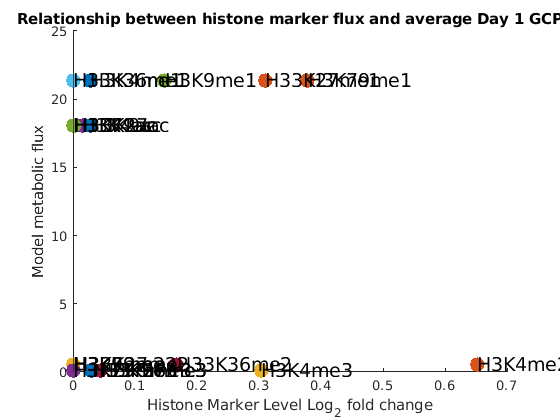

figure;
for i = 1:length(rxn_flux)
    hold on;
    scatter(data(i, 2), rxn_flux(i, 2), 120, 'filled');
    hold off;
end
xlabel("Histone Marker Level");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and average Day 1 GCP");
text(data(:, 2), rxn_flux(:, 2), marker_labels, 'FontSize', 14)
xline(0)

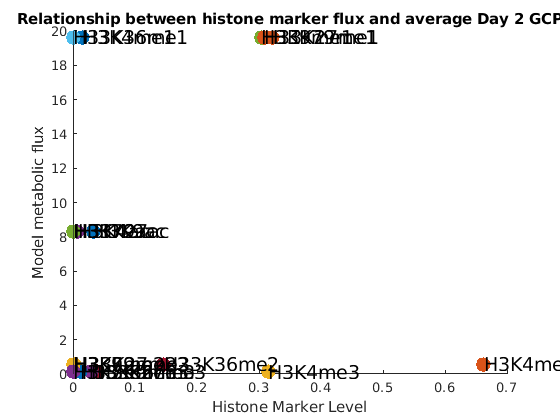

figure;
for i = 1:length(rxn_flux)
    hold on;
    scatter(data(i, 3), rxn_flux(i, 4), 120, 'filled');
    hold off;
end
xlabel("Histone Marker Level");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and average Day 2 GCP");
text(data(:, 3), rxn_flux(:, 4), marker_labels, 'FontSize', 14)
xline(0)

### Yadav et al

#### Load metabolic flux data

load ~/Data/CBM/eGEM/_Fluxes/yadav_no_gamma.mat

#### Load proteomics data

The values were visually inspected, and are indicative of percentages.

rel_abundance = [35, 30, 3, ... % H3K9 me1, me2, me3
                 22, 10,    ... % H3K79 me1, me2
                 16];        ... % H3K4 me1

marker_labels = ["H3K9me1", "H3K9me2", "H3K9me3", ...
                 "H3K79me1", "H3K79me2", ...
                 "H3K4me1"];

#### Plot the metabolic flux versus the relative proteomics levels

flux_pos = [10, 11, 12, ... % H3K9  me1, me2, me3
            22, 23, ...     % H3K79 me1, me2
            6];             % H3K4  me1
            
        
for i = 1:length(flux_pos)
    flux_data{i} = flux{flux_pos(i)};
end

rxn_pos = [3784, 3785, 3786, ... % H3K9  me1, me2, me3
           3796, 3797,       ... % H3K79 me1, me2
           3780];            ... % H3K4  me1
rxn_flux = [];           
for i = 1:length(rxn_pos)
    rxn_flux(i, 1) = flux_data{i}(rxn_pos(i));
end

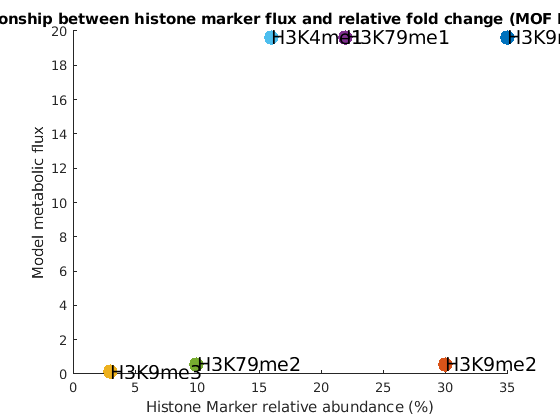

figure;
% Note that all markers were not differentially expressed
%for i = 1:length(rxn_flux)
%    if pvalues(i) > 0.05
%        colors(i) = 'k';
%   else
%        colors(i) = 'r';
%    end
%end
for i = 1:length(rel_abundance)
    hold on;
    scatter(rel_abundance(i), rxn_flux(i), 120, 'filled');
    hold off;
end
xlabel("Histone Marker relative abundance (%)");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and relative fold change (MOF KO / WT)");
text(rel_abundance, rxn_flux, marker_labels, 'FontSize', 14)
xline(0)